dir = fullfile('doc', 'examples', 'fsae-ttc-data');

file1 = fullfile(dir, 'fsaettc_obscured_testbench_drivebrake.mat');
file2 = fullfile(dir, 'fsaettc_obscured_testbench_cornering.mat');
parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements1 = parser.run(file1);
measurements2 = parser.run(file2);

measurements = [measurements1 measurements2];
measurements = measurements.downsample(10, 0);

fitmodes = {'Fx0','Fx','Fy0','Fy','Mz0','Mz','Mx'};

tyre = MagicFormulaTyre();
tyre.Parameters.NOMPRES.Value = max([measurements.NOMPRES]);
tyre.Parameters.FNOMIN.Value = max([measurements.FNOMIN]);
tyre.Parameters.UNLOADED_RADIUS.Value = 0.2025;

options = optimoptions('fmincon', 'Display', 'none');
options.MaxFunctionEvaluations = 1000;
tyre.fit(measurements, fitmodes, options)

Fitting Fx0...
Finished Fit-Mode: Fx0
Time elapsed 5.4s.

Fitting Fy0...
Finished Fit-Mode: Fy0
Time elapsed 6.3s.

Fitting Mz0...
Finished Fit-Mode: Mz0
Time elapsed 12.0s.

Fitting Fx...
Finished Fit-Mode: Fx
Time elapsed 23.7s.

Fitting Fy...
Finished Fit-Mode: Fy
Time elapsed 19.5s.

Fitting Mx...
Finished Fit-Mode: Mx
Time elapsed 3.1s.

Fitting Mz...
Finished Fit-Mode: Mz
Time elapsed 1.2s.



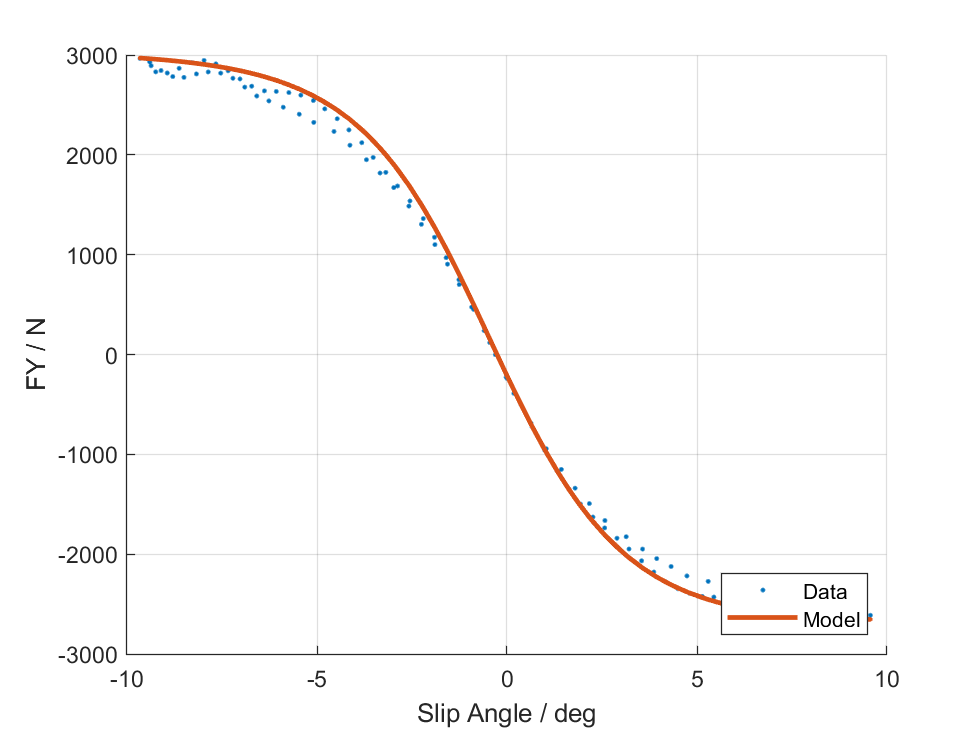

n = numel(measurements);
measurement = measurements(180);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX] = unpack(measurement);
[FX_mdl, FY_mdl, MZ_mdl, MY_mdl, MX_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

constants = {measurement.Constant.Name};
figure(); grid on; hold on
if any(contains(constants, 'SLIPANGL'))
    plot(SX, FX, '.')
    plot(SX, FX_mdl, '-', 'LineWidth', 2)
    ylabel('FX / N')
    xlabel('Slip Ratio / 1')
else
    plot(rad2deg(SA), FY, '.')
    plot(rad2deg(SA), FY_mdl, '-', 'LineWidth', 2)
    ylabel('FY / N')
    xlabel('Slip Angle / deg')
end
legend Data Model Location southeast

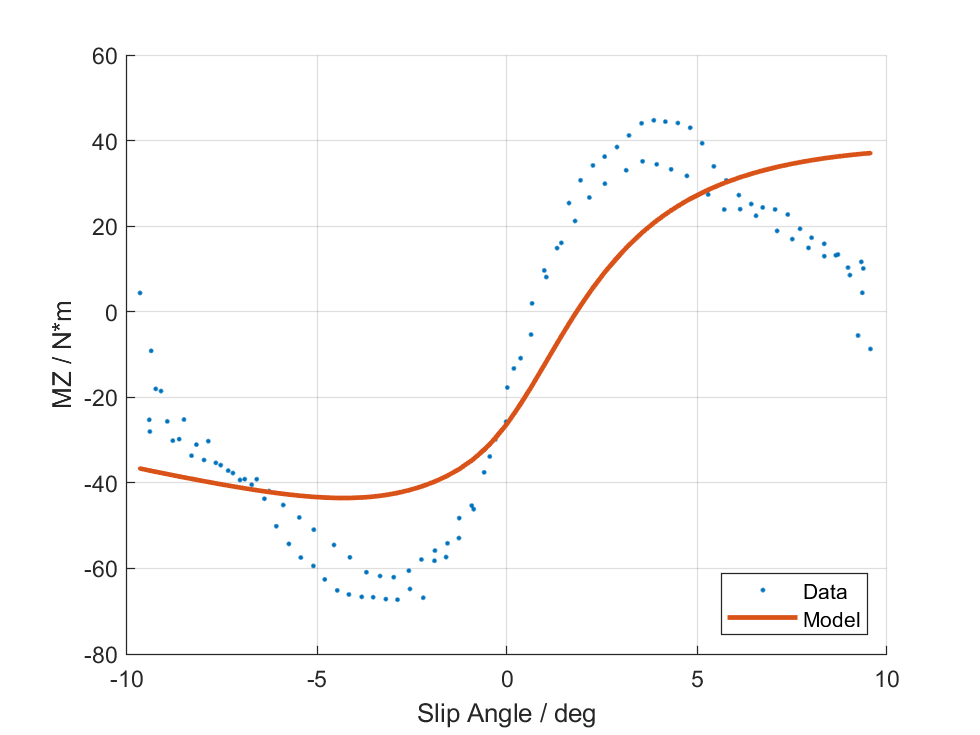


figure(); grid on; hold on
if any(contains(constants, 'SLIPANGL'))
    plot(SX, MZ, '.')
    plot(SX, MZ_mdl, '-', 'LineWidth', 2)
    ylabel('MZ / N*m')
    xlabel('Slip Ratio / 1')
else
    plot(rad2deg(SA), MZ, '.')
    plot(rad2deg(SA), MZ_mdl, '-', 'LineWidth', 2)
    ylabel('MZ / N*m')
    xlabel('Slip Angle / deg')
end
legend Data Model Location southeast

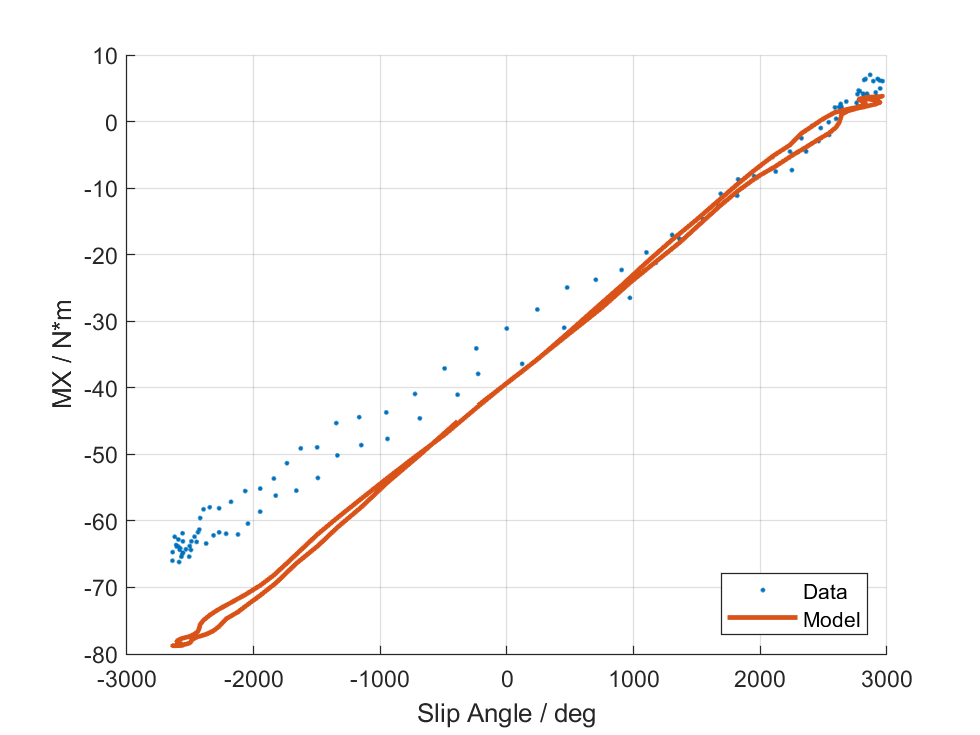


figure(); grid on; hold on
if any(contains(constants, 'SLIPANGL'))
    plot(SX, MX, '.')
    plot(SX, MX_mdl, '-', 'LineWidth', 2)
    ylabel('MX / N*m')
    xlabel('Slip Ratio / 1')
else
    plot(FY, MX, '.')
    plot(FY, MX_mdl, '-', 'LineWidth', 2)
    ylabel('MX / N*m')
    xlabel('Slip Angle / deg')
end
legend Data Model Location southeast